# MATLAB for MAT 124 MRSA Project

## Numerical Methods

% Run this section to clear the workspace
clear;clc;
% NOTE: Parameter variable names are shared and will be overwritten
%       for each section ran. Output is y(1,:), y(2,:), and y(3,:) for male model, 
%       and g(1,:), g(2,:), and g(3,:) for female model. Row 1 is S, Row 2
%       is C, and Row 3 is I.

## Male Model

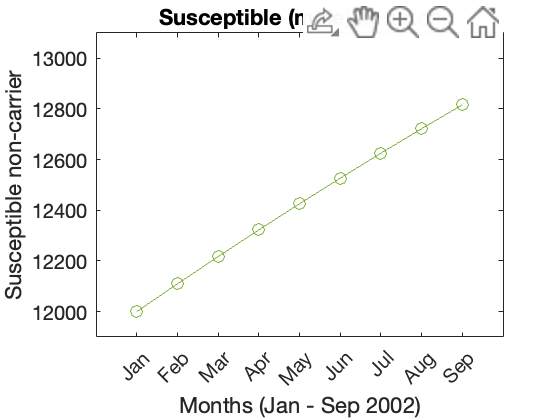

% Runge-Kutta method
% Parameters (midpoints if range) MALE MODEL
N = 16956;
pi = (341+407)/2;
delta = 1/((42+50)/2);
gamma_c = (8.8*10^(-5)+4.923*10^(-3))/2;
gamma_I = (8.8*10^(-5)+4.923*10^(-3))/2;
alpha = 1/((30+120)/2);
p = (0.10+0.30)/2;
phi = (4+15)/2;
beta_c = (1*10^(-5)+1.5*10^(-3))/2;
beta_I = (1*10^(-5)+1.5*10^(-3))/2;
c = (5+50)/2;

% Define function handles
% y=[R,F] <= y(1,:)=R y(2,:)=F
% y(1) = dS
% y(2) = dC
% y(3) = dI
f=@(t,y) [...
    +pi*(1-gamma_c-gamma_I)+alpha*y(2)-(c*beta_c*y(2)*y(1))/N-(c*beta_I*y(2)*y(1))/N-delta*y(1);
    +pi*(gamma_c)+(c*beta_c*y(2)*y(1))/N-(c*beta_I*y(3)*y(1))/N-alpha*y(2)-p*phi*y(2)-delta*y(2);
    +pi*(gamma_I)+p*phi*y(2)-delta*y(3)];

% Initial conditions
t(1) = 1;
y(:,1) = [12000,50,50];

% Step size
h = 1;
tfinal = 8;
M = ceil(tfinal/h);

% Update loop
for i = 1:M 
    % Update time
    t(i+1) = t(i)+h;
    % Update for y
    k1 = f(t(i)    ,y(:,i)       );
    k2 = f(t(i)+h/2,y(:,i)+k1*(h/2));
    k3 = f(t(i)+h/2,y(:,i)+k2*(h/2));
    k4 = f(t(i)+h  ,y(:,i)+h  *k3);
    y(:,i+1)=y(:,i)+h/6*(k1 + 2*k2 + 2*k3 + k4);
end

% Plot the solution
figure(1); clf(1);
plot(t,y(1,:), '-o', color = '#77AC30')
xlabel('Months (Jan - Sep 2002)')
ylabel('Susceptible non-carrier')
title('Susceptible (male) inmates')
% legend('Susceptible')
xlim([0 10])
xticks([1 2 3 4 5 6 7 8 9 10])
xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep'})
ylim([11900 13100])
ax = gca;
ax.YAxis.Exponent = 0;

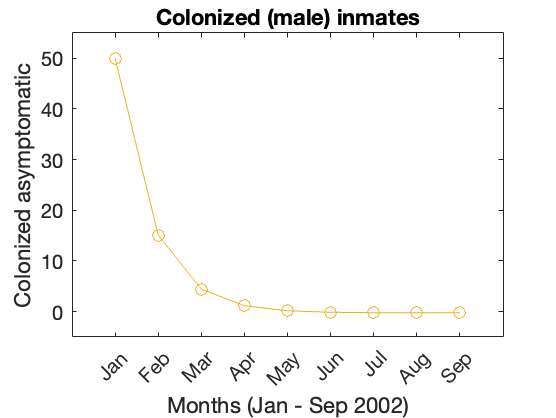

% set(gca, 'Fontsize', 16)
figure(2); clf(2);
plot (t,y(2,:), '-o', color = '#EDB120' )
xlabel('Months (Jan - Sep 2002)')
ylabel('Colonized asymptomatic')
title('Colonized (male) inmates')
% legend('Colonized')
xlim([0 10])
xticks([1 2 3 4 5 6 7 8 9 10])
xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep'})
ylim([-5 55])

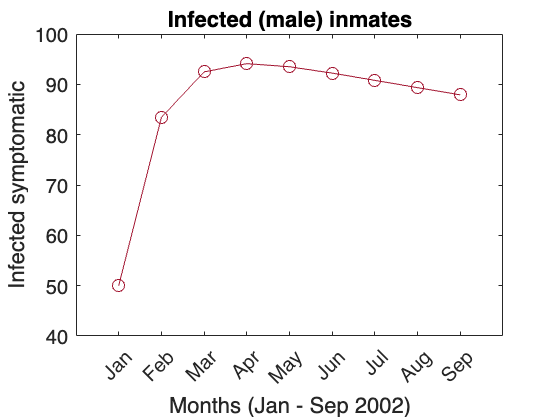

% set(gca, 'Fontsize', 16)
figure(3); clf(3);
plot (t,y(3,:), '-o', color = '#A2142F')
xlabel('Months (Jan - Sep 2002)')
ylabel('Infected symptomatic')
title('Infected (male) inmates')
% legend('Infected')
xlim([0 10])
xticks([1 2 3 4 5 6 7 8 9 10])
xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep'})
ylim([40 100])

% set(gca, 'Fontsize', 16)

## Female Model

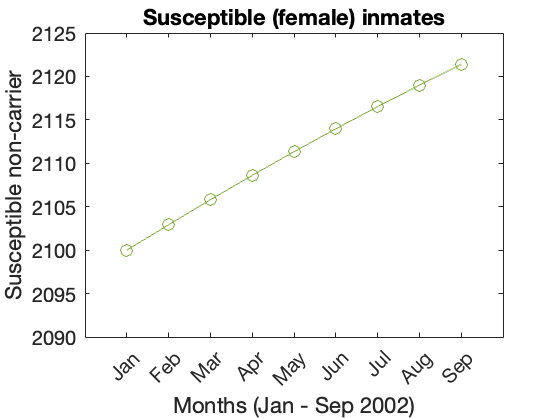

% Runge-Kutta method
% Parameters (midpoints if range) FEMALE MODEL
N = 2200;
pi = (64+81)/2;
delta = 1/((27+34)/2);
gamma_c = (4.43*10^(-4)+7.77*10^(-3))/2;
gamma_I = (4.43*10^(-4)+7.77*10^(-3))/2;
alpha = 1/((30+120)/2);
p = (0.10+0.30)/2;
phi = (4+15)/2;
beta_c = (1*10^(-5)+2*10^(-3))/2;
beta_I = (1*10^(-5)+2*10^(-3))/2;
c = (5+50)/2;

% Define function handles
% y=[R,F] <= y(1,:)=R y(2,:)=F
% y(1) = dS
% y(2) = dC
% y(3) = dI
f=@(t,g) [...
    +pi*(1-gamma_c-gamma_I)+alpha*g(2)-(c*beta_c*g(2)*g(1))/N-(c*beta_I*g(2)*g(1))/N-delta*g(1);
    +pi*(gamma_c)+(c*beta_c*g(2)*g(1))/N-(c*beta_I*g(3)*g(1))/N-alpha*g(2)-p*phi*g(2)-delta*g(2);
    +pi*(gamma_I)+p*phi*g(2)-delta*g(3)];

% Initial conditions
t(1) = 1;
g(:,1) = [2100,6,6];

% Step size
h = 1;
tfinal = 8;
M = ceil(tfinal/h);

% Update loop
for i = 1:M 
    % Update time
    t(i+1) = t(i)+h;
    % Update for y
    k1 = f(t(i)    ,g(:,i)       );
    k2 = f(t(i)+h/2,g(:,i)+k1*(h/2));
    k3 = f(t(i)+h/2,g(:,i)+k2*(h/2));
    k4 = f(t(i)+h  ,g(:,i)+h  *k3);
    g(:,i+1)=g(:,i)+h/6*(k1 + 2*k2 + 2*k3 + k4);
end

% Plot the solution
figure(1); clf(1);
plot(t,g(1,:), '-o', color = '#77AC30')
xlabel('Months (Jan - Sep 2002)')
ylabel('Susceptible non-carrier')
title('Susceptible (female) inmates')
% legend('Susceptible')
xlim([0 10])
xticks([1 2 3 4 5 6 7 8 9 10])
xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep'})
ylim([2090 2125])
ax = gca;
ax.YAxis.Exponent = 0;

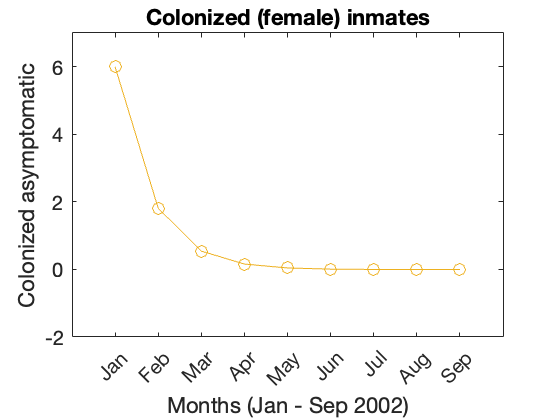

% set(gca, 'Fontsize', 16)
%
figure(2); clf(2);
plot (t,g(2,:), '-o', color = '#EDB120' )
xlabel('Months (Jan - Sep 2002)')
ylabel('Colonized asymptomatic')
title('Colonized (female) inmates')
% legend('Colonized')
xlim([0 10])
xticks([1 2 3 4 5 6 7 8 9 10])
xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep'})
ylim([-2 7])

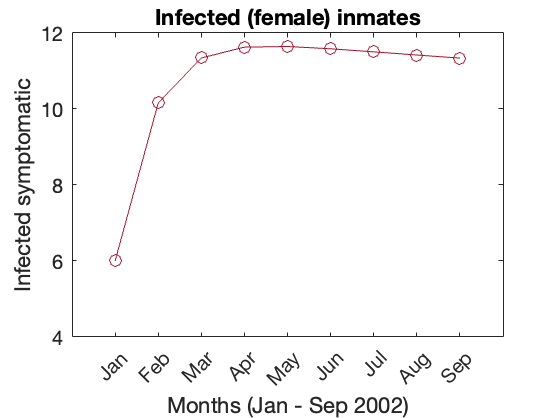

% set(gca, 'Fontsize', 16)
%
figure(3); clf(3);
plot (t,g(3,:), '-o', color = '#A2142F')
xlabel('Months (Jan - Sep 2002)')
ylabel('Infected symptomatic')
title('Infected (female) inmates')
% legend('Infected')
xlim([0 10])
xticks([1 2 3 4 5 6 7 8 9 10])
xticklabels({'Jan', 'Feb', 'Mar', 'Apr', 'May', 'Jun', 'Jul', 'Aug', 'Sep'})
ylim([4 12])

% set(gca, 'Fontsize', 16)